# COMSOL Plotter

Goal of this code is to extract and plot COMSOL outputs, manipulating them in ways not possiple with COMSOL


cd 'C:\Users\johns\Documents\Github\QEM-MATLAB\COMSOL Analysis'

addpath( ...
    'C:\Users\johns\Documents\Github\Gated-Mirror_xGANxSCAxGEM\200801 xGAN Full Module v1', ... % Time domain analysis from GaN paper
    'G:\My Drive\Code\LTSpice\200825 xGAN xGEM Load Responses V1\', ...  % LT Spice output response
    'C:\Users\johns\Documents\Github\QEM-MATLAB', ...    % Access to generic libraries
    'G:\My Drive\Code\COMSOL\xGAN Gated Mirror Sims\SMA Injection'); %new comsol stuff
    

load('ImpVariables.mat')

## 2D Data Importer

freqMin = 0.05*c.giga;
freqMax = 3.3*c.giga;
freqStep = 0.05*c.giga;
field.freq = freqMin:freqStep:freqMax;
sizeAr = size(field.freq)

sizeAr =      1    66



filename = 'xField_topPlane_grid.txt'

filename = 'xField_topPlane_grid.txt'

data=readtable(filename,'HeaderLines',8);

data=table2array(data);
field.x = data(1,1);
field.y = data(:,2);
field.z = data(:,3);
field.Ex = data(:,4:4+sizeAr(2)).';


## Reshape to Mesh Grid Approach

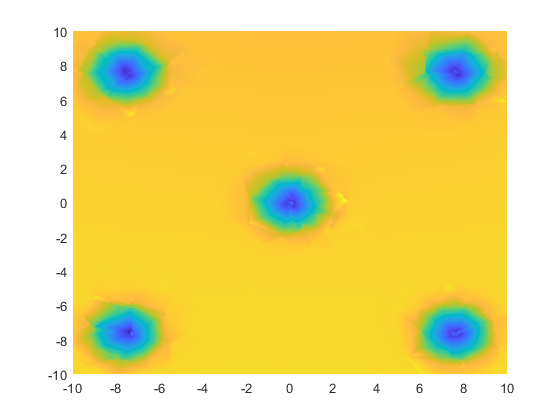

freqSelect = 4;
numPts = 201;
fieldPlot.y = field.y(1:numPts);
fieldPlot.Ex = reshape(field.Ex(3+freqSelect,:),[201,201]);
pcolor(real(fieldPlot.y), real(fieldPlot.y), abs(fieldPlot.Ex));
shading interp;


%plot3(field.y, field.z, field.Ex(4,:)),'o';

% % NO DC TERM IN RAW!
% field.freq = (data(:,1)).';
% field.posX 


## Raw Vector Approach

freqSelect = 66;
disp(['Chosen Frequency: ', num2str(field.freq(freqSelect)/c.giga), ' GHz'])

Chosen Frequency: 3.3 GHz


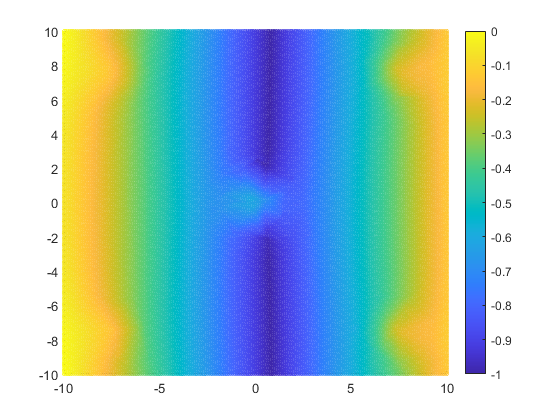



pointsize = 5;
fieldDC_Norm = abs(field.Ex(1,:)/field.Ex(1,1)); % Normalized electric field at 50 MHz normalized to a corner

%Normalized field to corner point 1 either directly plotted or as
%difference
fieldPlot = abs(field.Ex(freqSelect,:)/field.Ex(freqSelect,1)) - fieldDC_Norm;

%fieldPlot = abs(field.Ex(freqSelect,:)/field.Ex(freqSelect,1)) - fieldDC_Norm;

scatter3(real(field.y(:)), real(field.z(:)), fieldPlot , pointsize, fieldPlot) 
view([0 90]);
shading interp;
colormap(parula)
colorbar
caxis([-1,0])

## Line Plot Input

filename = 'xField_PropAxis_grid.txt'

filename = 'xField_PropAxis_grid.txt'

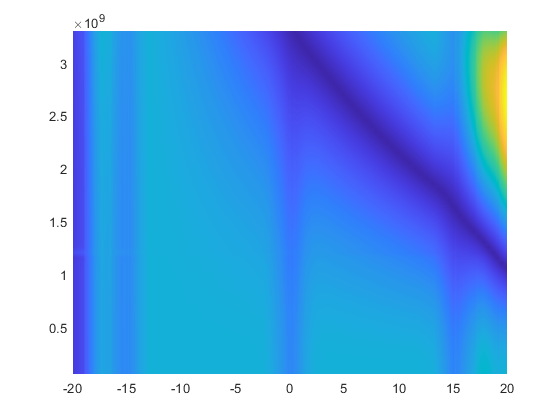

data=readtable(filename,'HeaderLines',9);
data=table2array(data);
propField.x = data(1,1);
propField.y = data(:,2);
propField.z = data(1,3);
propField.Ex = data(:,4:3+sizeAr(2)).';
normField = abs(propField.Ex);%.* real(propField.Ex)./abs(real(propField.Ex));

rescaleIndex =70;
for index = 1:66
    normFieldRescaled(index,:) = normField(index,:)/abs(normField(index,rescaleIndex));
end


plotField = (normFieldRescaled);
pcolor(real(propField.y), (real(field.freq)), plotField);
shading interp;